# Editing cage information

This guide explains how to change information about cage layouts and write the changes back to file.

## Example: changing cage positions

To demonstrate the editing of cage information, we'll change the location of the existing cages. First, we'll read the cages into Matlab and plot them

run  = project.solidsRuns.first;
site = run.cages

site =   Site with properties:

    cageGroups: {[8 Depomod.Layout.Cage.Group]}
          path: 'C:\newdepomod_projects\bay_of_fish\depomod\cages\bay_of_fish-1.depomodcagesxml'

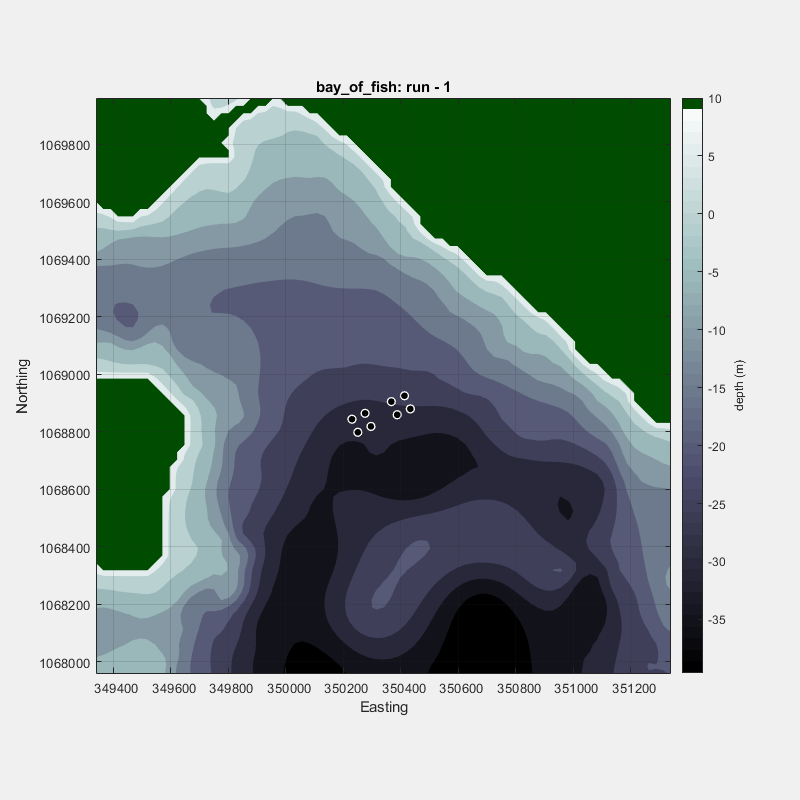

ans =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 0 600 600]
       Units: 'points'

  Show all properties


run.plot('impact', 0)

Okay, now we'll move the cages 200 m to the south by changing the `y` attribute on each cage.

no_cage_groups = site.size;

for g = 1:no_cage_groups % iterate through cage groups
    no_cages = site.cageGroups{g}.size;
    
    for c = 1:no_cages % iterate through cages
        y = site.cageGroups{g}.cages{c}.y;
        new_y = y + 200;
        
        site.cageGroups{g}.cages{c}.y = new_y;
    end
end

Now we need to tell the model run object to reference the adjusted cages object

run.cages = site;

Previously, we had copied the representation of the cages from the run object to the `site` variable, which we subsequently changed, leaving the original representation alone. So we need to replace the original in order to plot. Alternatively we could have applied all the cage changes directly to the cage object sitting on the run object, e.g.

 `run``.cages.cageGroups{g}.cages{c}.y = new_y`

etc. 

In any case, now we can plot the new cage positions.

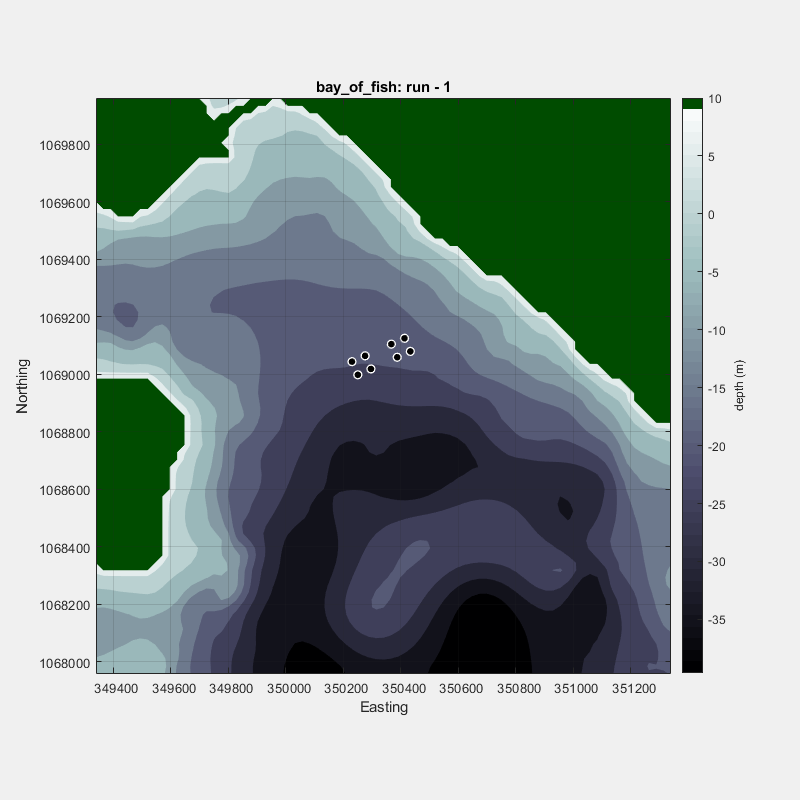

ans =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 0 600 600]
       Units: 'points'

  Show all properties

run.plot('impact',0)

Notice that the farms are now moved to the south. We can use a similar process to change other cage attributes.

## Saving new cage data

The current representation of cages held in the Matlab object can be written back to file for use in the NewDepomod software. 

site.toFile

or if a different file location is desired:

site.toFile('path\to\file.depomodcagesxml')

## Important

Writing new cage information to file causes the cages to be assigned a new `inputsId` value. This value must be referenced in a model run's inputs properties file and therefore it is necessary to synchronise these files for a successful model run.